- Implement generators of samples from Normal and Cauchy distributions. The generators should be functions parametrized by position (mean) and number of samples. You can keep the variance fixed.

function [norm, cauchy] = generator(sz, mu, sigma)
    norm = normrnd(mu, sigma, sz);
    cauchy = mu+sigma * trnd(1, sz);
end

2. Using library functions, compute histograms of test statistics for T-Test and Mann-Whitney-U tests for the following three cases:

(a) Under hypothesis H0, the two compared sets of samples are sampled from the same distribution. We recommend to sample them from Normal(0,1).

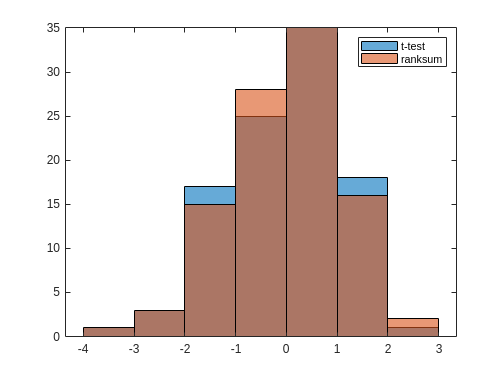

mu = 0;
sz = [1000, 1];

res = zeros([100, 2]);

for i = 1:length(res)
    [norm_x1, ~] = generator(sz, mu, 1);
    [norm_x2, ~] = generator(sz, mu, 1);
    
    [~, ~, ~, stat] = ttest2(norm_x1, norm_x2);
    res(i,1) = stat.tstat;

    [~, ~, stat] = ranksum(norm_x1,norm_x2);
    res(i,2) = stat.zval;
end

histogram(res(:,1))
hold on
histogram(res(:,2))
hold off
legend("t-test", "ranksum")

(b) Under hypothesis H1a , the two compared sets of samples are sampled from two different distributions, but both distributions are normal. We recommend to sample them from Normal(0,1) and Normal(3,1).

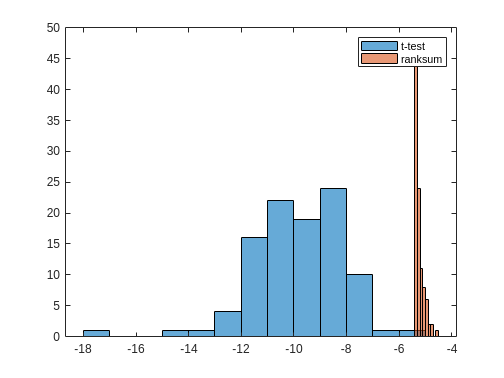

mu1 = 0;
mu2 = 3;
sz = [20, 1];

res = zeros([100, 2]);

for i = 1:length(res)
    [norm_x1, ~] = generator(sz, mu1, 1);
    [norm_x2, ~] = generator(sz, mu2, 1);
    
    [~, ~, ~, stat] = ttest2(norm_x1, norm_x2);
    res(i,1) = stat.tstat;

    [~, ~, stat] = ranksum(norm_x1,norm_x2);
    res(i,2) = stat.zval;
end

histogram(res(:,1))
hold on
histogram(res(:,2))
hold off
legend("t-test", "ranksum")

(c) Under hypothesis H1b , the two compared sets of samples are sampled from two different distributions and the distributions are different. We recommend to sample them from Normal(0,1) and Cauchy(3,1).

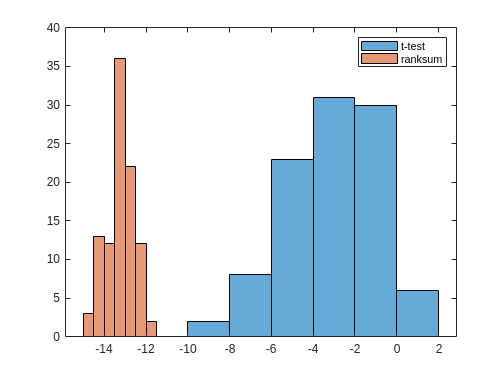

mu1 = 0;
mu2 = 3;
sz = [200, 1];

res = zeros([100, 2]);

for i = 1:length(res)
    [norm_x1, ~] = generator(sz, mu1, 1);
    [~, cauchy_x2] = generator(sz, mu2, 1);
    
    [~, ~, ci, stat] = ttest2(norm_x1, cauchy_x2);
    res(i,1) = stat.tstat;

    [~, ~, stat] = ranksum(norm_x1,cauchy_x2);
    res(i,2) = stat.zval;
end

histogram(res(:,1))
hold on
histogram(res(:,2))
hold off
legend("t-test", "ranksum")

3. Add to the plot distribution of the test statistic under null hypothesis H0 for both tests. For the TTest, the test statistic follows Student-t distribution with 2n − 2 degrees of freedom (where n is the sample size). 

You should observe that distributions fitting the histogram do not change despite changing parameters of the distribution under H0 hypothesis.